Круглый цилиндр, H-поляризация

По методу из гибсона для сравнения.

21_10_20

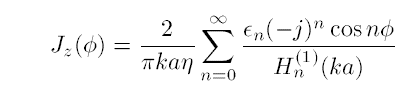

Гибсон стр 113

close all;
clear variables;


% исходные данные
R = 2;
N = 200;
n_harmonic = 100; % кол-во гармоник

% константы
eta = 120*pi;
k = 2*pi; 


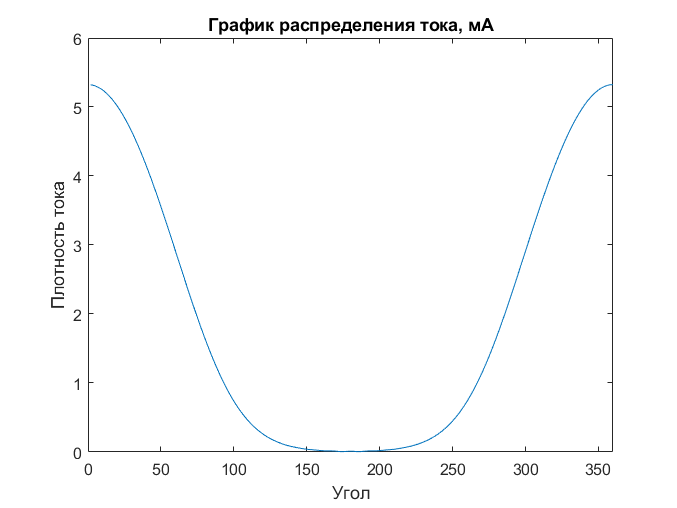

% генерация углов и списка углов
delta_phi = 360/N;
for i = 1 : N 
    phi_list(i) = delta_phi*i; % список углов
end

% кол-во точек
for n_dot = 1 : N
    
    % текужщий угол
    current_phi = phi_list(n_dot);
      
    % кол-во гармоник
    Sum = 0;
    for n = 1 : n_harmonic
        if (n-1) == 0
            epsilon = 1;
        else
            epsilon = 2;
        end

        Sum = Sum + epsilon*(-1i)^(n-1)*cosd((n-1)*current_phi)/besselh((n-1),1, k*R);        
    end
    
    I(n_dot) = 2/(pi*k*R*eta)*Sum;
end

% в соотвествии с литературой умножим на 1000
ImA = abs(I)*1000;

plot(phi_list, ImA)
title('График распределения тока, мА'); 
xlabel('Угол'); 
xlim([0,360])
ylabel('Плотность тока');

Запись в файл токов

f01 = fopen('I_Gibson_Epol.dat','w');

for n=1:N
    fprintf(f01,' %10.5f %10.5f\n', phi_list(n), ImA(n));
end

fclose(f01);